# Radar Systems Laboratory - A.A. 2022/2023

Master Degree in Telecommunication Engineering, University of Pisa

- **Note for Linux users:** I had some problems with Ubuntu, the OS wanted all the permissions to the serial ports. Type in Terminal: `sudo chmod 666 /dev/tty*`

## Fifth example: range waterfall | 29-11-2022

This live script initialises the serial connection with the evaluation board, it sets the parameters of the radar and starts the acquisition. It acquires a number of frames that depends on `acquisitionTime` variable. It builds a matrix where a row corresponds to a frame and does the range compression, obtaining a range-time image. The trigger for the measurement is manual. The next trigger is done when "Enter" is pressed.

### Initialisation

clear
fclose('all');

fprintf("\nRetrieving port ...\n")


Retrieving port ...



sPort = serialportlist;
baudRate = 1e6;

### Serial port setting

This part may require some changes, depending on the number of serial ports that is found by `serialportlist().`

serialPort = sPort;
fprintf("Connecting to %s ...\n",serialPort)

Connecting to /dev/ttyUSB0 ...


com_port = serialport(serialPort,baudRate);

set(com_port, "DataBits", 8);
set(com_port, "Parity", 'none');
set(com_port, "StopBits", 1);
set(com_port, "Timeout", 1);
configureTerminator(com_port,'CR/LF');

ref: [https://it.mathworks.com/help/matlab/ref/serialport.html](https://it.mathworks.com/help/matlab/ref/serialport.html) 

### Radar setting

- **"!S08021010": **linear magnitude, TSV output, output on SER1, external trigger mode

- **"!K": **it sets the maximum available bandwidth, $6\ldotp 1\;\textrm{GHz}$;

- **"!B20000008": **DC cancellation on, 1 ramp, 64 samples

fprintf("\nSetting the radar ...\n")


Setting the radar ...



writeline(com_port,"!S08039012")
writeline(com_port,"!K")
writeline(com_port,"!B200000F0")    %1 rampa, 64 campioni
%writeline(com_port,"!B200000D8")    %8 rampa, 256 campioni

nSamples = 2048;
BW = 6.1e9;
c = 3e8;
calFactor = 37.5;

zeroPadding = 4;
nfft = zeroPadding*nSamples;

maxRange = ((nSamples + calFactor)*c)/(4*BW);
rangeVec = (0:2*maxRange/nfft:maxRange - maxRange/nfft)*100;

The following equation can be found in the SiRad Simple datasheet: 

$T_{ramp} = t_{smp}\cdot \frac{n\degree  Samples + 37.5}{36MHz}$ , $\qquad \qquad \qquad (1)$ 

where $t_{\textrm{smp}}$ is expressed in clock cycles, the values can be found in the **Table 19 **of the datasheet. The FMCW equation **[1]**:

$\frac{f_b}{\tau} = \frac{B}{T_{ramp}} $ ,$\qquad \qquad \qquad (2)$ 

where $f_b$ is the beat frequency, $\tau \;$is the transit time delay and $B$ is the bandwidth of the system, can be used to calculate the maximum achievable range, by considering that:

$f_b^{max} = \frac{f_s}{2} = \frac{36MHz}{2t_{smp}}$   and   $\tau = \frac{2R_{max}}{c}$ , $\qquad \qquad \qquad (3)$ 

By substituing equations $\left(1\right)$and $\left(3\right)$ in equation $\left(2\right)$, we can write the maximum achievable range:


$$R_{max} = \frac{\left(n\degree  Samples + 37.5\right)\cdot c}{4\cdot B}$$
  
$$\qquad \qquad \qquad (2)$$
 

- **Note: **the "calibration factor" (i.e., 37.5) is different from the one written in the datasheet. 

### Acquisition and plot

At the beginning of the `while `loop, a trigger command is sent to the board and the data is sent back from the radar. In the received string, the I samples are on odd indices, while the Q samples are on even indices. The complex data vector is built and assigned to a matrix. This matrix will contain a range profile per row. After that, the code saves the matrix and waits for a keyboard input to repeat the process.

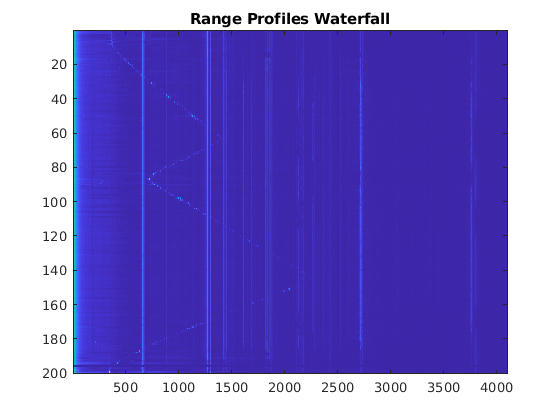

Saving file: data_2022_11_28_18_29_10


acquisitionTime = 10; %seconds
PRI = 50e-3;
nFrames = round(acquisitionTime/PRI);
waterfallMat = zeros(nFrames,nSamples);

%figure
%imagesc(zeros(nFrames,nfft))

while true
    for ind = 1:nFrames
        buf = '';
        while isempty(buf) || ~startsWith(buf,'!M')
            buf = readline(com_port);
        end
    
        frameM = split(buf);
        frameM = frameM(4:end);
        
        dataM = str2double(frameM);
        dataI = dataM(1:2:end-1);
        dataQ = dataM(2:2:end);
        
        complexData = (dataI + 1i*dataQ).';
        if length(complexData) == nSamples
            waterfallMat(ind,:) = complexData;
        end
    end

    rangeProfiles = fft(waterfallMat,nfft,2);
    imageToPlot = abs(rangeProfiles(:,1:end/2));

    imagesc(imageToPlot)
    %xlabel("Distance [cm]")
    %ylabel("Magnitude [dB]")
    title('Range Profiles Waterfall')

    c = strsplit(strjoin(string(clock),'_'),'.');
    file_name = strcat('data_',c(1));
    save(file_name,'waterfallMat','BW','nSamples','nFrames')
    fprintf("Saving file: %s\n", file_name)
    pause(10)
end

### References

**[1] **James A. Scheer, James L. Kurtz (editors). “Coherent Radar Performance Estimation”. Boston: Artech House (1993), ISBN 0-89006-628-0.